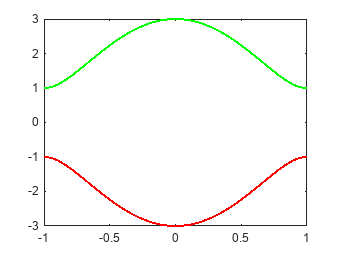

% Clear workspace, command window, and close all figures
clear;
clc;
close all;


N = 51; % Example value, you can change it
g = 0.1;   % Coupling strength g
J = 2;   % Coupling constant J
J_prime = 1; % Coupling constant J'
omega = 5; % Modulation frequency omega
Delta = omega * 0.2;  % Detuning parameter Delta
V = 0.2;   % Modulation amplitude V
j_0 = (N-1)/2;
k = -pi:0.01:pi;

Ek = sqrt(J^2 + J_prime^2 + 2 * J * J_prime .* cos(k));
Gamma = (J + J_prime) * V.* (sin(k) ./  Ek);
tilde_E = sqrt((Ek - omega/2).^2 + Gamma.^2);

figure;
plot(k/pi, Ek, 'g', 'LineWidth', 1.5);
hold on;
plot(k/pi, -Ek, 'r', 'LineWidth', 1.5);
hold off;

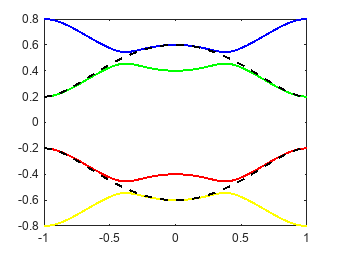



figure;
plot(k/pi, (tilde_E + omega/2) / omega, 'b', 'LineWidth', 1.5);
hold on;
plot(k/pi, (tilde_E - omega/2) / omega, 'r', 'LineWidth', 1.5);
plot(k/pi, (-tilde_E + omega/2) / omega, 'g', 'LineWidth', 1.5);
plot(k/pi, (-tilde_E - omega/2) / omega, 'y', 'LineWidth', 1.5);
plot(k/pi, Ek/omega, 'k--', 'LineWidth', 1.5);
plot(k/pi, -Ek/omega, 'k--', 'LineWidth', 1.5);